clc; clearvars;
% Tạo các điểm mẫu
point1 = Point([1, 0, 0], [1 0 0 0], 'Frame1');
point2 = Point([0, -1.2, 0], [1 0 0 0], 'Frame2');
point3 = Point([2, -1, 0], [1 0 0 0], 'Frame3');
O = Point();
% Gọi hàm để tính toán các thông số của đường tròn từ ba điểm
[circleCenter, circleRadius, angleBetweenPoints, isClockwise] = circleFromThreePoints(point1, point2, point3)

circleCenter =     0.9909   -1.0091         0


circleRadius = 1.0091

angleBetweenPoints = -4.7304

isClockwise = logical
   0


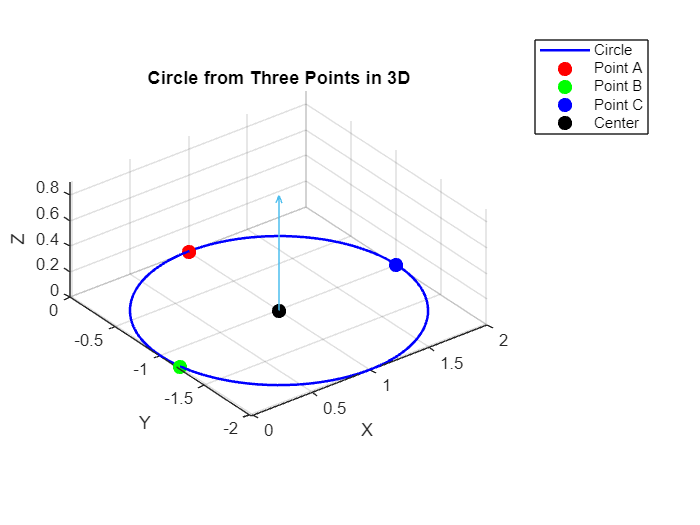

plotCircle3D(circleCenter,circleRadius,point1, point2, point3);

point4 = Point(circleCenter, [1 0 0 0], 'Frame3');

% Gọi hàm để tính toán các thông số của đường tròn từ hai điểm và tâm
[circleRadius, angleBetweenPoints, isClockwise] = circleFromTwoPointsAndCenter(point1, point3, point4)

circleRadius = 1.0091

angleBetweenPoints = 1.5528

isClockwise = logical
   1


plotCircle3D(circleCenter,circleRadius,point1, point2, point3);plotCircle3D(circleCenter,circleRadius,point1, point2, point3);


function plotCircle3D(center, radius, p1, p2, p3)
    % Extract positions
    A = p1.Position;
    B = p2.Position;
    C = p3.Position;
    
    % Normal vector to the plane
    normal = cross(B - A, C - A);
    normal = normal / norm(normal);
    
    % Parametric circle equation in the plane
    theta = linspace(0, 2*pi, 100);
    v = null(normal); % Two orthogonal vectors in the plane
    
    % Circle points
    circlePoints = center' + radius * (v(:,1) * cos(theta) + v(:,2) * sin(theta));
    
    % Plot the circle
    plot3(circlePoints(1,:), circlePoints(2,:), circlePoints(3,:), 'b-', 'LineWidth', 1.5);
    hold on;
    
    % Plot the points
    plot3(A(1), A(2), A(3), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
    plot3(B(1), B(2), B(3), 'go', 'MarkerSize', 8, 'MarkerFaceColor', 'g');
    plot3(C(1), C(2), C(3), 'bo', 'MarkerSize', 8, 'MarkerFaceColor', 'b');
    
    % Plot the center
    plot3(center(1), center(2), center(3), 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k');
    quiver3(center(1), center(2), center(3), normal(1), normal(2), normal(3));
    % Labels
    legend('Circle', 'Point A', 'Point B', 'Point C', 'Center');
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    title('Circle from Three Points in 3D');
    grid on;
    axis equal;
    hold off;
end